vidReader = VideoReader('part1.mp4','CurrentTime',1);
h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);
opticFlows = opticalFlowHS

opticFlows =   opticalFlowHS with properties:

            Smoothness: 1
          MaxIteration: 10
    VelocityDifference: 0


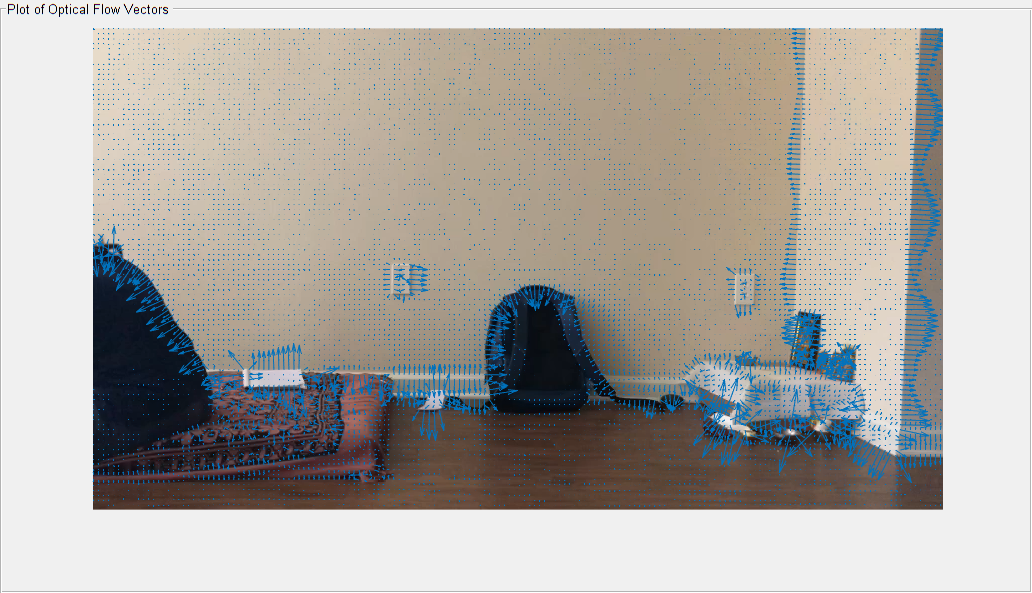

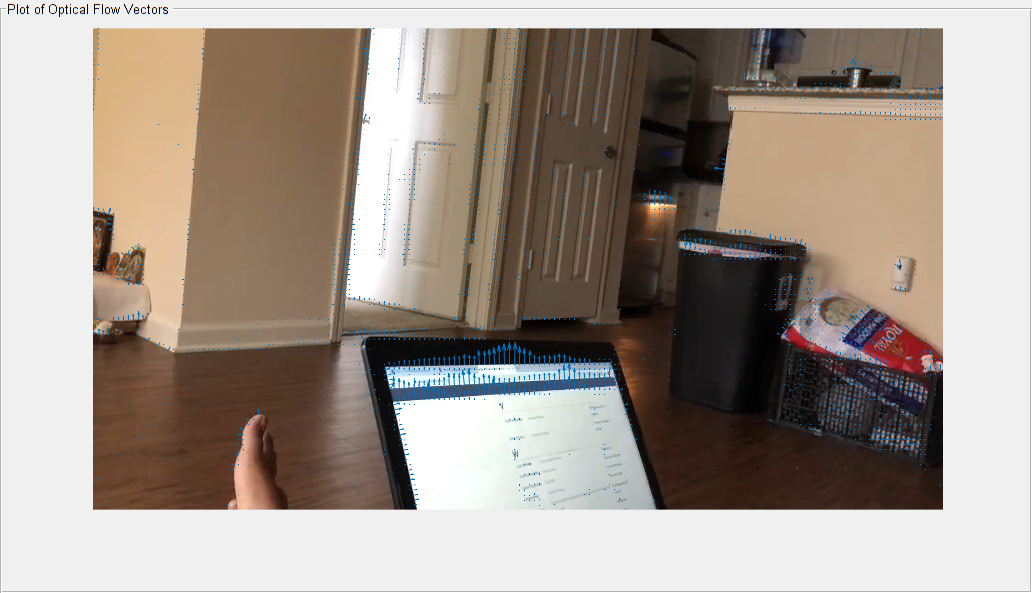

%floww = estimateFlow(opticFlow,frameGrayy);

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);
    img2 = im2double(frameGray);
    RGB = imread('Frame11.jpg');
    frameGrayy = im2gray(RGB); 
    img1 = im2double(frameGrayy);
    opticFlow = opticalFlow(img1,img2);
    flow = estimateFlow(opticFlows,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
    hold off
    pause(10^-3)
end